# Loop Statement

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2019-05-03

## For Loop

### Simple example I

Generate a row vector having scalar values from 11 to 20 with 1 interval

% THINK ABOUT THE ANSER BEFORE LOOKING AT SAMPLE CODES



row_vec1 = 11:20;

for ii=1:10
    row_vec2(ii) = ii+10;
end
% not recommend: the size of row_vec2 is changed on every loop

row_vec3 = zeros(1, 10);
for ii=1:10
    row_vec3(ii) = ii+10;
end
% recommended if you need to use for-loop

row_vec4 = zeros(1, 10);
for ii=[1:10]
    row_vec4(ii) = ii+10;
end
% you can assign any vector as a range 

row_vec5 = [];
for ii=11:20
    row_vec5 = [row_vec5 ii];    
end
% not recommend: the size of row_vec5 is changed on every loop

% all vectors are identical
row_vec1

row_vec1 =     11    12    13    14    15    16    17    18    19    20


row_vec2

row_vec2 =     11    12    13    14    15    16    17    18    19    20


row_vec3

row_vec3 =     11    12    13    14    15    16    17    18    19    20


row_vec4

row_vec4 =     11    12    13    14    15    16    17    18    19    20


row_vec5

row_vec5 =     11    12    13    14    15    16    17    18    19    20


### Simple example II

Sum 1 to 10 and assign its value to a variable

% THINK ABOUT THE ANSER BEFORE LOOKING AT SAMPLE CODES



A1 = 1+2+3+4+5+6+7+8+9+10;

A2 = 0;
for ii=1:10
    A2 = A2 + ii;
end

A3 = (1+10)*10/2; % use an equation

A4 = sum(1:10); % use a built-in function

% all values are identical
A1

A1 = 55

A2

A2 = 55

A3

A3 = 55

A4

A4 = 55

### **Nested loop**

for ii=1:3
    for jj=1:2
        [ii jj]
    end
end

ans =      1     1


ans =      1     2


ans =      2     1


ans =      2     2


ans =      3     1


ans =      3     2


% the inner loop is executed in its all iterations for every value of the
% outer loop variable.  nchoosek

### Combining for-loop and if

Change 1 to 5, 2 to 7, and the rest to 10 in a given vector

% THINK ABOUT THE ANSER BEFORE LOOKING AT SAMPLE CODES



vec = [1 1 2 1 3 1 6 7 5];

vec_new1 = zeros(size(vec));
% vec_new1 = vec; vec_new1 = 0; % same result
for ii=1:numel(vec_new1)
    if vec(ii)==1
        vec_new1(ii) = 5;
    elseif vec(ii)==2
        vec_new1(ii) = 7;
    else
        vec_new1(ii) = 10;
    end
end

vec_new2 = zeros(size(vec));
vec_new2(vec==1) = 5;
vec_new2(vec==2) = 7;
vec_new2((vec~=1)&(vec~=2)) = 10;
% recommend: logical indexing can clearn out your code. 

vec_new3 = ones(size(vec))*10;
vec_new3(vec==1) = 5;
vec_new3(vec==2) = 7;
% we can save one more line

% all vectors are identical
vec_new1

vec_new1 =      5     5     7     5    10     5    10    10    10


vec_new2

vec_new2 =      5     5     7     5    10     5    10    10    10


vec_new3

vec_new3 =      5     5     7     5    10     5    10    10    10


### **More examples**

#### Example 1

Find indexes of a vector where 5 is located

% THINK ABOUT THE ANSER BEFORE LOOKING AT SAMPLE CODES



vec = [1 5 6 4 8 5 3 7 8 5 9 10];

loc1 = find(vec == 5); % it is starightforward to use a 'find' function

% note that we do not know the size of loc2
loc2 = [];
for ii=1:numel(vec)
    if vec(ii)==5
        loc2 = [loc2 ii];
    end
end
% the size of loc2 is changed on every loop

loc3 = zeros(1, numel(vec));
count = 0;
for ii=1:numel(vec)
    if vec(ii)==5
        count = count + 1;
        loc3(count) = ii;        
    end
end
loc3 = loc3(1:count);
% If we know the maximum size that it could possibly be, we can preallocate to a size of the loc3.
% And then delete the “unused” elements.  
% In order to do that, you would have to count the number of elements that are actually used.

% all vectors are idetnfical
loc1

loc1 =      2     6    10


loc2

loc2 =      2     6    10


loc3

loc3 =      2     6    10


#### Example 2

Find indexes of a matrix where 5 is located

% THINK ABOUT THE ANSER BEFORE LOOKING AT SAMPLE CODES



vec = [1 5 6 4 8 5 3 7 8 5 9 10];
matrix = reshape(vec, 3,4); % it is matrix

% these two column vectors are equal
isequal(vec', matrix(:))

ans = logical
   1



[I, J] = find(matrix==5);
loc_rc1 = [I J];
% use of a built-in function (two ouput from the function)

loc_idx = find(matrix(:)==5);
[I, J] = ind2sub(size(matrix), loc_idx);
loc_rc2 = [I J];
% use of a built-in function
% Finiding a location of 5 using a linear indexing
% conveting a single (linearly indexed) index into row and column indexes

loc_rc3 = [];
[rsize, csize] = size(matrix);
for ii=1:rsize
    for jj=1:csize
        if matrix(ii,jj)==5
            loc_rc3 = [loc_rc3;[ii jj]];
        end
    end
end
% not recommend: the size of loc_rec3 is changed on every loop.

loc_rc4 = zeros(numel(matrix), 1);
count = 0;
[rsize, csize] = size(matrix);
for ii=1:csize
    for jj=1:rsize
        if matrix(jj,ii)==5
            count = count + 1;
            loc_rc4(count, 1:2) = [jj ii];
        end
    end
end
loc_rc4 = loc_rc4(1:count,:);
% it is better than the previous one but care should be taken when you deal
% with 'count'. 

% they indicate same rows and columns for the position of 5
loc_rc1

loc_rc1 =      2     1
     3     2
     1     4


loc_rc2

loc_rc2 =      2     1
     3     2
     1     4


loc_rc3

loc_rc3 =      1     4
     2     1
     3     2


loc_rc4

loc_rc4 =      2     1
     3     2
     1     4


## **While-loop**

### Simple example

% do you know what this code is?
count = 0;
val = 0;
while count~=11
    val = val + count;
    count = count + 1;
end

val

val = 55

### Break

for ii=1:10
    ii
    if ii==5
        break;
    end
end

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

% check out the printed result

### More example

Find an first 4th index of 5 in a given vector

% THINK ABOUT THE ANSER BEFORE LOOKING AT SAMPLE CODES



vec = [1 5 2 3 5 6 7 4 5 5 6 3 4 5 6 8 5];

tmp = find(vec==5, 4);
idx1 = tmp(end); clearvars tmp
% it's a good practice to delete variables that you will not  use anymore

count = 0;
idx2 = 0;
while count ~=4
    idx2 = idx2 + 1;
    if vec(idx2)== 5
        count = count + 1;
    end
end

count = 0;
idx3 = 1;
while count ~=4
    if vec(idx3)== 5
        count = count + 1;
    end
    idx3 = idx3 + 1;
end
idx3 = idx3 - 1;
% Compare the code for idx2 and idx3
% You should pay attention to the location of the "idx" phrase. Depending
% on its location, the value is varied. 

count = 0;
idx4 = 0;
while 1
    idx4 = idx4 + 1;
    if vec(idx4)== 5
        count = count + 1;
        if count==4
            break;
        end
    end
end
% More often, there are many exit conditions in your while loop. In this
% case, you will introduce break. (however, in this example, there is one 
% exit


count = 0;
idx5 = 0;
for ii=1:numel(vec)
    if vec(ii) == 5
        count = count + 1;
        if count==4
            idx5 = ii;
            break;
        end
    end
end
% this example is to introduce how you can design a for-loop to do the same
% operation from a while-loop

tmp = cumsum(vec==5);
idx6 = find(tmp==4, 1);
% can you understand this code? you are a MATLAB expert.

% all values are idetnfical
idx1

idx1 = 10

idx2

idx2 = 10

idx3

idx3 = 10

idx4

idx4 = 10

idx5

idx5 = 10

idx6

idx6 = 10

## Vectorization

### Dot product 

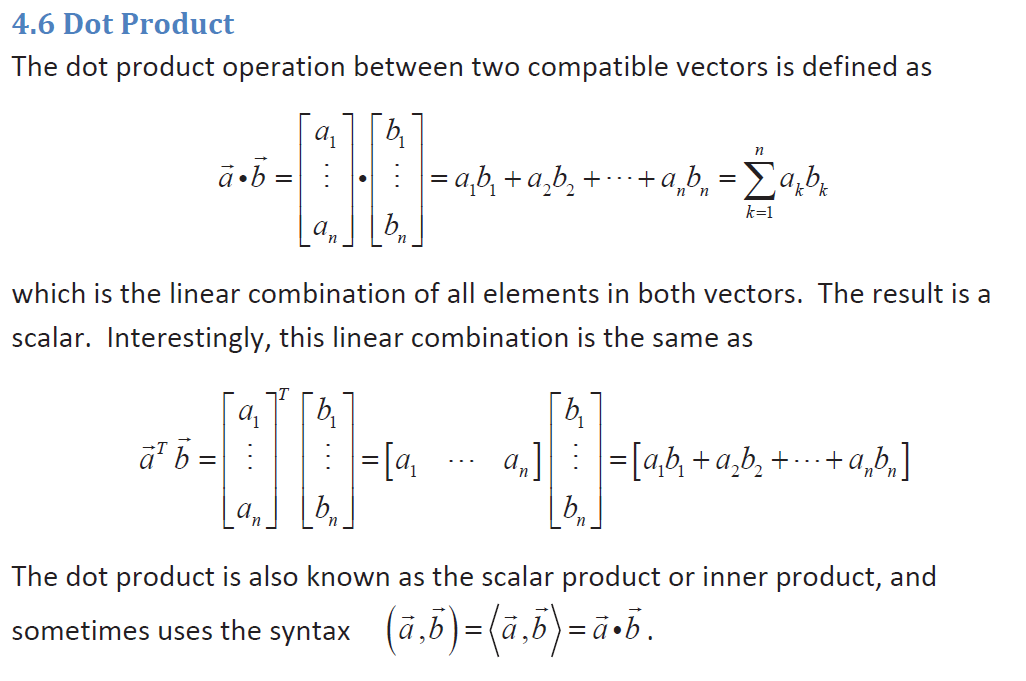

*<from the Dr. Brush's lecture note>*

Compute a dot product between two row vectors (A and B):


$$\begin{array}{l}
\mathit{\mathbf{A}}=\left\lbrack 3\;4\;5\;6\;8\right\rbrack \\
\mathit{\mathbf{B}}=\left\lbrack 5\;6\;7\;7\;8\right\rbrack 
\end{array}$$


% THINK ABOUT THE ANSER BEFORE LOOKING AT SAMPLE CODES



% dot product
A = [3 4 5 6 8];
B = [5 6 7 7 8];

AB1 = dot(A,B); % use of a built-in function

AB2vec = zeros(1,5); % again, do not set zeros(5) because it is a 5 x 5 matrix
for ii=1:numel(A)
    AB2vec(ii) = A(ii)*B(ii);
end
AB2 = sum(AB2vec);
% it is direct convesion of the dot operation. 

AB3 = 0;
for ii=1:5
    AB3 = AB3 + A(ii)*B(ii);
end
% we can make shorter the code like this.

AB4 = 0;
for ii=1:numel(A)
    AB4 = AB4 + A(ii)*B(ii);
end
% coding tip: We knew that the size of A is 1 x 5. However, assuem that your code is
% getting longer and your collegue may review your code. 5 may not be clear
% about what value indicates. It is a good practice use numel(A) instead of
% 5. You can define a scalr variable regarding its array size like
%
% size_A = numel(A)
% for ii=1:size_A

AB5 = sum(A.*B); 
% I expect that you will write a code like this at the end of course. 
% In this case, in most cases, there is a built-in function (here, 'dot'),
% but not always. You need to learn a skill to write this code based on the
% definition of the dot product. 

AB6 = A*B';
% Super! Can you see the difference between * and .*? and understand how
% this is working? You are amazing. 

% all values are identical
AB1

AB1 = 180

AB2

AB2 = 180

AB3

AB3 = 180

AB4

AB4 = 180

AB5

AB5 = 180

AB6

AB6 = 180

### (Advanced) Debug example

% assume that you put a wrong dimention vector A (it's supposed to be 1x6)
A = [3 4 5 6 10];
B = [4 5 7 8 11 12];

Compare error messages from different dot product methods. Which one is more helpful for debugging?  

% AB1error = dot(A,B)

% AB3error = 0;
% for ii=1:6
%     AB3error = AB3error + A(ii)*B(ii);
% end

What happend if you run this code? This is the worst case. If you write this code, you nevel find the error. 

% AB4error = 0;
% for ii=1:numel(A)
%     AB4error = AB4error + A(ii)*B(ii);
% end


Here is a sample code if you are not aware of a built-in function and shuold use a loop statement:

% AB4error = 0;
% assert(numel(A)==numel(B), 'A and B must be the same size.')
% for ii=1:numel(A)
%     AB4error = AB4error + A(ii)*B(ii);
% end

This code can readily catch your mistake in advance. 